# Optimización de una función no lineal usando `fminunc` en MATLAB

**Profesor:** PhD. Marlon E. Moscoso Martínez

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
f = @(x) (x - 2).^2 + 1.5;

% Punto inicial para el solver
x0 = 0;  % Puedes seleccionar otro valor inicial si lo deseas

% Usar fminunc para encontrar el mínimo
options = optimoptions('fminunc', 'Display', 'iter', 'Algorithm', 'quasi-newton');
[x_opt, fval, exitflag, output] = fminunc(f, x0, options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           2              5.5                             4
     1           4              2.5           0.25              2  
     2           6              1.5              1       2.98e-08  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% Mostrar el resultado
disp('Punto óptimo:');

Punto óptimo:


disp(x_opt);

     2



disp('Valor de la función en el punto óptimo:');

Valor de la función en el punto óptimo:


disp(fval);

    1.5000



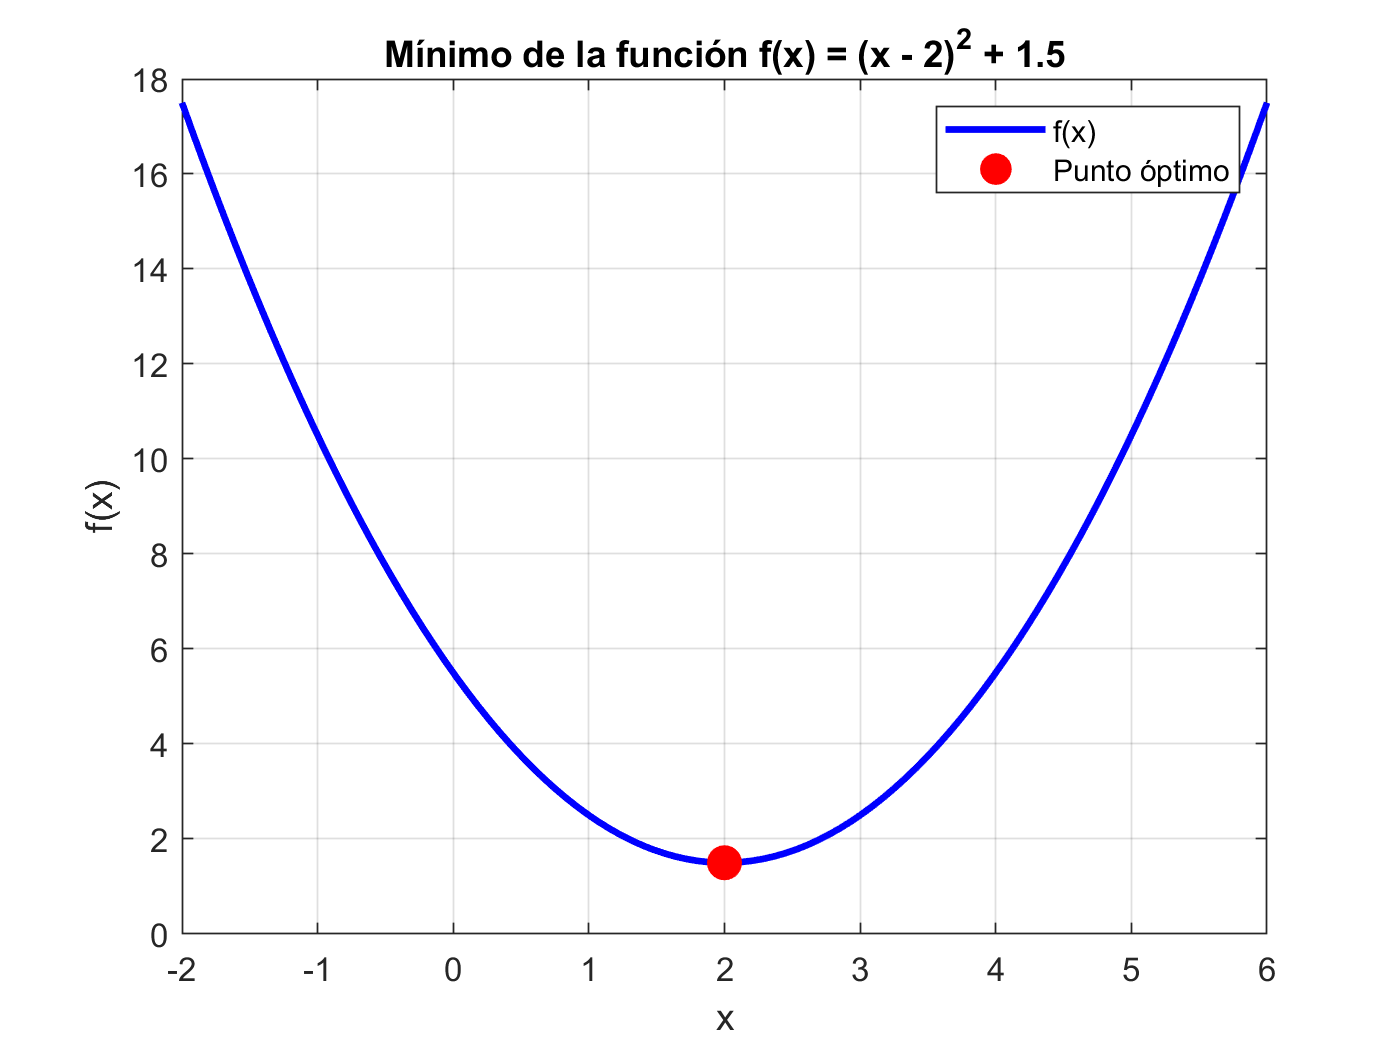


% Graficar la función
x_values = linspace(-2, 6, 100);  % Valores para graficar la función
y_values = f(x_values);

figure;
plot(x_values, y_values, 'b-', 'LineWidth', 2);
hold on;
plot(x_opt, fval, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');  % Punto óptimo
title('Mínimo de la función f(x) = (x - 2)^2 + 1.5');
xlabel('x');
ylabel('f(x)');
legend('f(x)', 'Punto óptimo');
grid on;
hold off;